# PRÁCTICA 3: Selección de características

## Objetivos

- Implementar diferentes métodos de extracción de características

- Comparar resultados entre distintos métodos de selección de características

- Analizar el impacto de la reducción dimensional

## Introducción

La selección de características es fundamental en el campo del reconocimiento de patrones y el aprendizaje automático. Su propósito radica en identificar variables o atributos más informativos dentro de un conjunto de datos, descartando aquellos que son redundantes, irrelevantes o ruidosos. Este proceso no solo mejora la eficiencia computacional, sino que también eleva la capacidad de generalización de los modelos, permitiéndoles identificar patrones subyacentes evitando el sobreajuste (overfitting). Este proceso, que consiste en identificar el equilibrio entre la simplificación y la optimización, trabajar con menos datos, pero de mayor calidad.

### La importancia de la selección de características

En problemas de alta dimensionalidad, donde el número de carcaterísticas puede superar ampliamente la cantidad de muestras, la selección de estas características se vuelve crítica. Por ejemplo, en imágenes médicas o datos genómicos, es común tener miles de variables, muchas de las cuales pueden ser correlacionadas o carecer de valor predictivo. Al recucir la dimensionalidad, los algoritmos evitan considerar información irrelevante, enfocándose en los atributos clave que definen los patrones. Además, modelos más simples son más interpretables, un aspecto que sobresale en áreas como la medicina o ciencias sociales, donde entender por qué un modelo toma una decisión es tan importante como su precisión.

### Desafíos y consideraciones prácticas

La selección de características continúa teniendo muchos retos. Uno de los más significativos es el manejo de relaciones no lineales o complejas entre variables. Por ejemplo, en problemas de visión artificial, la textura de una imagen puede depender de la interacción no aditiva entre pixeles vecinos, algo que métodos lineales como la correlación podrían pasar por alto. Pero técnicas basadas en métodos no paramétricos (como el análisis de componentes independientes) pueden ser más apropiados.

Otro desafío es la estabilidad, en donde un conjunto de datos con alto nivel de ruido o muestras limitadas, pueden variar significativamente los subconjuntos seleccionados entre particiones de entrenamiento y validación. Esto afecta a la confiabilidad del modelo, especialmente en aplicaciones críticas como el diagnóstico médico. Para mitigarlo, se recomienda usar técnicas de validación cruzada robustas o métodos de consenso. Adicionalmente, es crucial evitar un enfoque limitado que priorice características individualmente relevantes pero descarte grupos complementarios. Como puede ser el caso del procesamiento del lenguaje natural (NLP), palabras como *no* o* nunca* pueden parecer irrelevantes en un análisis univariado, pero son esenciales para entender el sentimiento negativo cuando se combinan con otros términos.

Por último, el análisis comparativo integra perspectivas estadísticas (pruebas de hipótesis sobre diferencias en precisión y exactitud), computacionales (complejidad de algoritmos) y geométricas (proyecciones en espacios reducidos), ofreciendo una visión más amplia del problema de selección de características en sistemas de reconocimiento de patrones

## Desarrollo

**Ejercicio:** Selección de características con el conjunto de datos Wine

1. **Utilizar el conjunto de datos Wine** (UCI Machine Learning Repository). Este conjunto de datos multidimensional describe propiedades químicas de tres variedades de vinos y cuenta con 178 muestras, 13 características químicas. Este conjunto de datos presenta un escenario ideal para explorar técnicas de reducción dimensional, ya que combina atributos correlacionados (como concentraciones de fenoles y flavonoides) con características potencialmente discriminativas (como el color o la alcalinidad).

    a) Verificar la integridad del conjunto de datos (valores faltantes, rangos válidos)

2. Preparación de datos

    a) Normallizar los datos (z-score)

    b) Cargar el dataset y dividirlo en 70% entrenamiento y 30% prueba

    c) Crear un clasificador base (KNN con k=3 vecinos)

3. Implementación de métodos

    a) **Búsqueda exhaustiva**

- Modificar código para seleccionar 5 características

- Analizar resultados

    b) **Búsqueda secuencial hacia adelante (SFS)**

- Ejecutar con validación

- Generar gráfico de exactitud por características

    c) **Fisher**

- Implementar función del cálculo Score de separabilidad entre clases

- Selecciona las 5 características con mayor puntuación

    d) **Rama y límite (B&B)**

- Comparar con SFS

- Analizar resultados

    e) **PCA**

- Determinar componentes para 95% de varianza

- Visualizar proyección 2D

4. Análisis comparativo

    a) Crear tabla comparativa con:

- Método

- Características seleccionadas

- Métricas de entrenamiento y pruebas

- Comentar los mejores resultados

5. Análisis de resultados

    a) ¿Qué método obtuvo mejor exactitud? ¿Por qué?

    b) ¿Cómo afecta la correlación entre características al PCA?

    c) ¿Qué ventajas tiene Fisher Score sobre SFS en términos computacionales?

## Código

clear; close all; clc;
format shortG;

### **1. Utilizar el conjunto de datos Wine**

wine = readtable('Wine.csv');

X = wine{:, 1:13};    % Características
Y = wine{:, 14};       % Etiquetas

**a) Verificar la integridad del conjunto de datos (valores faltantes, rangos válidos)**

%% Valores faltantes
% Para las características (X)
missing_X = ismissing(X);
total_missing_X = sum(missing_X(:)); % Cuenta todos los valores faltantes en X

if total_missing_X > 0
    disp(['Se encontraron ', num2str(total_missing_X), ' valores faltantes en las características (X).']);
    % Mostrar cuántos faltan por columna
    missing_per_column_X = sum(missing_X);
    disp('Valores faltantes por columna en X:');
    disp(missing_per_column_X);
else
    disp('No se encontraron valores faltantes en las características (X).');
end

No se encontraron valores faltantes en las características (X).


% Para las etiquetas (Y)
missing_Y = ismissing(Y);
total_missing_Y = sum(missing_Y); % Y es un vector columna

if total_missing_Y > 0
    disp(['Se encontraron ', num2str(total_missing_Y), ' valores faltantes en las etiquetas (Y).']);
else
    disp('No se encontraron valores faltantes en las etiquetas (Y).');
end

No se encontraron valores faltantes en las etiquetas (Y).


% Rangos y tipos de datos
disp(['Tipo de datos de X: ', class(X)]);

Tipo de datos de X: double


min_X = min(X);
max_X = max(X);
disp('Mínimo de cada característica:');

Mínimo de cada característica:


disp(min_X);

        11.03         0.74         1.36         10.6           70         0.98         0.34         0.13         0.41         1.28         0.48         1.27          278



disp('Máximo de cada característica:');

Máximo de cada característica:


disp(max_X);

        14.83          5.8         3.23           30          162         3.88         5.08         0.66         3.58           13         1.71            4         1680



disp(['Tipo de datos de Y: ', class(Y)]);

Tipo de datos de Y: double


% Mostrar las clases
unique_Y = unique(Y);
disp('Valores únicos en Y (Clases):');

Valores únicos en Y (Clases):


disp(unique_Y);

     1
     2
     3



% Contar cuántas instancias hay por clase
counts_Y = histcounts(Y, [unique_Y; unique_Y(end)+1]);
for i = 1:length(unique_Y)
    disp(['Clase ', num2str(unique_Y(i)), ': ', num2str(counts_Y(i)), ' instancias']);
end

Clase 1: 59 instancias
Clase 2: 71 instancias
Clase 3: 48 instancias


% Obtener los nombres de las características
featureNames = wine.Properties.VariableNames(1:13);

### **2. Preparación de datos**

**a) Normallizar los datos (z-score)**

X = zscore(X);

**b) Cargar el dataset y dividirlo en 70% entrenamiento y 30% prueba**

rng(123);  % Para reproducibilidad
cv = cvpartition(Y, 'HoldOut', 0.3);
X_train = X(cv.training,:);
Y_train = Y(cv.training);
X_test = X(cv.test,:);
Y_test = Y(cv.test);

**c) Crear un clasificador base (KNN con k=3 vecinos)**

% Parámetros comunes
k = 5;  % Número de características a seleccionar
classifier = @(XTRAIN, YTRAIN, XTEST) predict(fitcknn(XTRAIN, YTRAIN, 'NumNeighbors',3), XTEST);

### **3. Implementación de métodos**

** a) Búsqueda exhaustiva**

fprintf('--- Búsqueda Exhaustiva ---\n');

--- Búsqueda Exhaustiva ---


n_features = 5;
comb = nchoosek(1:13, n_features);
best_acc = 0;
best_subset = [];

for i = 1:size(comb,1)
    acc = sum(classifier(X_train(:,comb(i,:)), Y_train, X_test(:,comb(i,:))) == Y_test)/numel(Y_test);
    if acc > best_acc
        best_acc = acc;
        best_subset = comb(i,:);
    end
end

% Mostrar resultados de busqueda exhaustiva
best_feature_names_cell_a = featureNames(best_subset);
best_feature_names_string_a = strjoin(best_feature_names_cell_a, ', ');
fprintf('Mejor subconjunto (5 características): %s\n', best_feature_names_string_a);

Mejor subconjunto (5 características): Alcohol, Malic_Acid, Magnesium, Flavanoids, Color_Intensity


% Usamos el mejor subconjunto encontrado
X_train_bf = X_train(:, best_subset);
X_test_bf = X_test(:, best_subset);

% Predecir en entrenamiento y calcular exactitud de entrenamiento
predictions_train_bf = classifier(X_train_bf, Y_train, X_train_bf);
accuracy_train_bf = sum(predictions_train_bf == Y_train) / numel(Y_train);

% Predecir en prueba y calcular exactitud de prueba
predictions_test_bf = classifier(X_train_bf, Y_train, X_test_bf);
accuracy_test_bf = sum(predictions_test_bf == Y_test) / numel(Y_test);
fprintf('  Exactitud Entrenamiento: %.2f%%\n', accuracy_train_bf * 100);

  Exactitud Entrenamiento: 94.40%


fprintf('  Exactitud Prueba:        %.2f%%\n', accuracy_test_bf * 100);

  Exactitud Prueba:        100.00%


**Análisis: **Las características con mejor potencial discriminatorio, utilizando búsqueda exhaustiva son: *Alcohol, Malic_Acid, Magnesium*, *Flavanoids *y *Color_Intensity*. Se alcanzó un 100% de exactitud en las pruebas, sin embargo esto solo significa que, al menos, para el clasificador KNN (con k=3) y esta división en particular de los datos, las características son muy efectivas para separar las clases.Aun cabe la posibilidad de que sea por casualidad, pero este subconjunto es prometedor, ya que la precision de entrenamiento tambien tiene una precision razonabemente buena.

**b) Búsqueda secuencial hacia adelante (SFS)**

fprintf('--- Búsqueda Secuencial Forward ---\n');

--- Búsqueda Secuencial Forward ---


opts = statset('Display','iter', 'UseParallel',true);
rng(123);  % Para reproducibilidad
c = cvpartition(Y_train, 'kfold', 5);

[fs_sfs, history] = sequentialfs(@(XTRAIN, YTRAIN, XTEST, YTEST) ...
    sum(classifier(XTRAIN, YTRAIN, XTEST) ~= YTEST), ...
    X_train, Y_train, 'cv',c, 'options',opts, 'nfeatures',k);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 13, criterion value 0.248
Step 2, added column 12, criterion value 0.096
Step 3, added column 10, criterion value 0.064
Step 4, added column 7, criterion value 0.04
Step 5, added column 8, criterion value 0.032
Final columns included:  7 8 10 12 13 


% Mostrar resultados de SFS
best_feature_names_cell_b = featureNames(fs_sfs);
best_feature_names_string_b = strjoin(best_feature_names_cell_b, ', ');
fprintf('Mejor subconjunto (5 características): %s\n', best_feature_names_string_b);

Mejor subconjunto (5 características): Flavanoids, Nonflavanoid_Phenols, Color_Intensity, OD280, Proline


% Usamos el subconjunto seleccionado por SFS (fs_sfs)
X_train_sfs = X_train(:, fs_sfs);
X_test_sfs = X_test(:, fs_sfs);

% Predecir en entrenamiento y calcular exactitud de entrenamiento
predictions_train_sfs = classifier(X_train_sfs, Y_train, X_train_sfs);
accuracy_train_sfs = sum(predictions_train_sfs == Y_train) / numel(Y_train);

% Predecir en prueba y calcular exactitud de prueba
predictions_test_sfs = classifier(X_train_sfs, Y_train, X_test_sfs);
accuracy_test_sfs = sum(predictions_test_sfs == Y_test) / numel(Y_test);
fprintf('  Exactitud Entrenamiento: %.2f%%\n', accuracy_train_sfs * 100);

  Exactitud Entrenamiento: 99.20%


fprintf('  Exactitud Prueba:        %.2f%%\n', accuracy_test_sfs * 100);

  Exactitud Prueba:        98.11%


% Extraer el orden en que las características fueron seleccionadas por SFS
% history.In es una matriz lógica donde history.In(i,j) es true
% si la característica j está incluida en el subconjunto de tamaño i.

sfs_feature_order = zeros(1, k); % k es el número final de características seleccionadas (5)

% La primera característica seleccionada es la única que es true en la fila 1
sfs_feature_order(1) = find(history.In(1,:));

% Para las características subsiguientes (del paso 2 al k),
% la característica añadida en el paso 'i' es la que es true en history.In(i,:)
% pero era false en history.In(i-1,:).
for i = 2:k
    % Encuentra el índice que es true en la fila i y false en la fila i-1
    idx_added = find(history.In(i,:) & ~history.In(i-1,:));
    sfs_feature_order(i) = idx_added;
end
fprintf('\nOrden de características seleccionadas por SFS: %s\n', strjoin(featureNames(sfs_feature_order), ', '));


Orden de características seleccionadas por SFS: Proline, OD280, Color_Intensity, Flavanoids, Nonflavanoid_Phenols


%% Calcular Exactitud en el Conjunto de Prueba paso a paso
% Evaluaremos el modelo en X_test/Y_test añadiendo características
% en el orden determinado por sfs_feature_order.

test_accuracies_by_step = zeros(1, k); % Para almacenar la exactitud en cada paso
current_feature_subset_logical = false(1, size(X_train, 2)); % Índice lógico inicial (ninguna característica)

fprintf('\nCalculando Exactitud en el conjunto de test para cada paso SFS:\n');


Calculando Exactitud en el conjunto de test para cada paso SFS:


for i = 1:k
    % Añadir la siguiente característica en el orden SFS al subconjunto lógico
    next_feature_idx = sfs_feature_order(i);
    current_feature_subset_logical(next_feature_idx) = true; % Marcar la característica como seleccionada

    % Obtener los datos de entrenamiento y prueba con el subconjunto actual de características
    X_train_subset = X_train(:, current_feature_subset_logical);
    X_test_subset = X_test(:, current_feature_subset_logical);

    % Entrenar el clasificador en el subset de entrenamiento y predecir en el subset de prueba
    predictions = classifier(X_train_subset, Y_train, X_test_subset);

    % Calcular la exactitud para este paso y almacenarla
    current_acc = sum(predictions == Y_test) / numel(Y_test);
    test_accuracies_by_step(i) = current_acc;

    % Mostrar el progreso
    subset_names = strjoin(featureNames(current_feature_subset_logical), ', ');
    fprintf('  Paso %d (%d caract.): %s -> Exactitud Prueba: %.2f%%\n', ...
            i, sum(current_feature_subset_logical), subset_names, current_acc*100);
end

  Paso 1 (1 caract.): Proline -> Exactitud Prueba: 62.26%
  Paso 2 (2 caract.): OD280, Proline -> Exactitud Prueba: 92.45%
  Paso 3 (3 caract.): Color_Intensity, OD280, Proline -> Exactitud Prueba: 92.45%
  Paso 4 (4 caract.): Flavanoids, Color_Intensity, OD280, Proline -> Exactitud Prueba: 98.11%
  Paso 5 (5 caract.): Flavanoids, Nonflavanoid_Phenols, Color_Intensity, OD280, Proline -> Exactitud Prueba: 98.11%


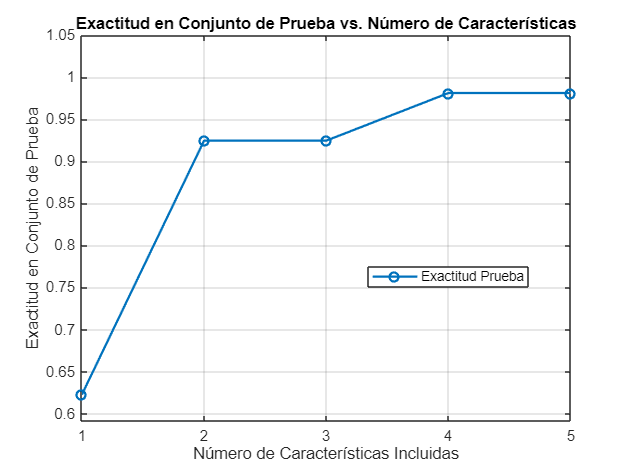

% Grafico de Exactitud en test vs. Numero de Caracteristicas
figure;
plot(1:k, test_accuracies_by_step, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Exactitud Prueba');

title('Exactitud en Conjunto de Prueba vs. Número de Características');
xlabel('Número de Características Incluidas');
ylabel('Exactitud en Conjunto de Prueba');
xticks(1:k);
ylim([min(test_accuracies_by_step)*0.95, 1.05]);
grid on;
legend('Location', 'best');

** c) Fisher**

function score = fisher_score(feature, labels)

--- Fisher Score ---


    classes = unique(labels);
    n_classes = length(classes);
    overall_mean = mean(feature);
    
    between = 0;
    within = 0;
    
    for i = 1:n_classes
        idx = (labels == classes(i));
        n_i = sum(idx);
        mean_i = mean(feature(idx));
        var_i = var(feature(idx),1);

Características seleccionadas: Flavanoids, Proline, OD280, Alcohol, Color_Intensity


        
        between = between + n_i*(mean_i - overall_mean)^2;
        within = within + n_i*var_i;
    end
    
    score = between / within;
end

fprintf('--- Fisher Score ---\n');
fisher_scores = zeros(1,13);
for i = 1:13
    fisher_scores(i) = fisher_score(X_train(:,i), Y_train);
end

[~, fisher_idx] = sort(fisher_scores, 'descend');
selected_fisher = fisher_idx(1:k);

  Exactitud Entrenamiento: 97.60%


  Exactitud Prueba:        98.11%


% Mostrar resultados de fisher
best_feature_names_cell_c = featureNames(selected_fisher);
best_feature_names_string_c = strjoin(best_feature_names_cell_c, ', ');

--- B&B ---


fprintf('Características seleccionadas: %s\n', best_feature_names_string_c);
% Crear los subconjuntos de datos de entrenamiento y prueba
X_train_fisher = X_train(:, selected_fisher);
X_test_fisher = X_test(:, selected_fisher);

% Hacer predicciones en el conjunto de entrenamiento
% Entrenamos con X_train_fisher y probamos con X_train_fisher
predictions_train_fisher = classifier(X_train_fisher, Y_train, X_train_fisher);
accuracy_train_fisher = sum(predictions_train_fisher == Y_train) / numel(Y_train);

% Hacer predicciones en el conjunto de prueba
% Entrenamos con X_train_fisher y probamos con X_test_fisher
predictions_test_fisher = classifier(X_train_fisher, Y_train, X_test_fisher);
accuracy_test_fisher = sum(predictions_test_fisher == Y_test) / numel(Y_test);

% Mostrar las exactitudes
fprintf('  Exactitud Entrenamiento: %.2f%%\n', accuracy_train_fisher * 100);
fprintf('  Exactitud Prueba:        %.2f%%\n', accuracy_test_fisher * 100);

**d) Rama y límite (B&B)**

fprintf('--- B&B ---\n');
function selIdx = b_and_b(X_tr, Y_tr, k)
% FISHERBNB   Selección de k características por Branch&Bound usando Fisher score.
%   selIdx = b_and_b(X_tr, Y_tr, k)
%   — X_tr: n×d matriz de entrenamiento
%   — Y_tr: n×1 vector de etiquetas

Características seleccionadas: Flavanoids, Proline, OD280, Alcohol, Color_Intensity


%   — k:   número de características a seleccionar
%   — selIdx: vector de índices (1…d) de las k características elegidas

    [nSamples, d] = size(X_tr);
    classes = unique(Y_tr);
    K = numel(classes);

    %--- 1) Cálculo de Fisher score F(j) por cada feature j ---
    pk = zeros(K,1);
    mu_k = zeros(K,d);
    var_k = zeros(K,d);
    for ik = 1:K

  Exactitud Entrenamiento: 97.60%


        mask = (Y_tr==classes(ik));

  Exactitud Prueba:        98.11%


        pk(ik) = sum(mask)/nSamples;
        mu_k(ik,:) = mean(X_tr(mask,:),1);
        var_k(ik,:) = var (X_tr(mask,:),1,1);

--- PCA ---


    end
    mu_all = mean(X_tr,1);
    Sb = sum(pk.*(mu_k - mu_all).^2, 1);
    Sw = sum(pk.*var_k, 1);
    F  = Sb./Sw;

    %--- 2) Prepara orden descendente y sumas acumuladas para poda ---
    [F_sorted, idx_sorted] = sort(F,'descend');
    % S_acum(i) = sum(F_sorted(i:end))

Componentes seleccionados: 10


    S_acum = [0, cumsum(F_sorted, 'reverse')];

    %--- 3) Branch & Bound recursivo ---
    bestScore = -inf;
    bestSet   = zeros(1,k);

    % arranca la búsqueda
    bnb([], 0, 1);


Reducción PCA (10 componentes):


    % devuelve índices en el espacio original

  Exactitud Entrenamiento: 96.80%


    selIdx = idx_sorted(bestSet);

  Exactitud Prueba:        98.11%


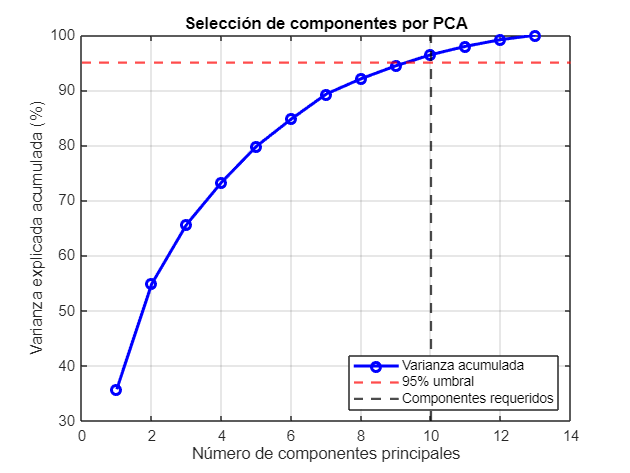


    %--- nested function para B&B ---
    function bnb(currSet, currScore, nextPos)
        % si ya elegimos k, actualiza mejor solución
        if numel(currSet)==k
            if currScore>bestScore
                bestScore = currScore;
                bestSet   = currSet;
            end
            return
        end
        % cuántas faltan y hasta dónde podemos iterar
        toPick = k - numel(currSet);

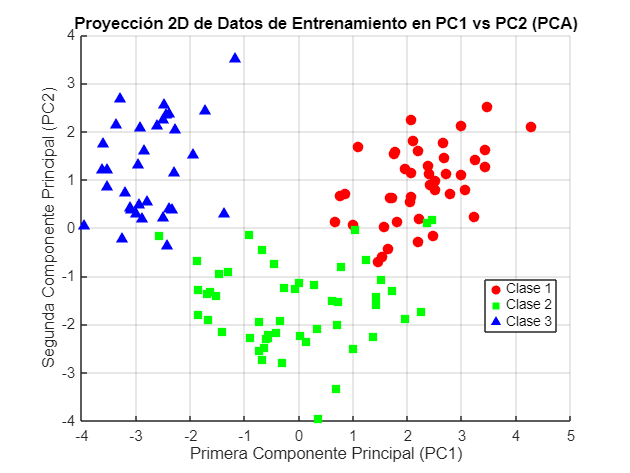

        maxStart = numel(F_sorted) - toPick + 1;

        for i = nextPos : maxStart
            % cota superior (score actual + sum de los mejores `toPick` restantes)
            bestRem = S_acum(i) - S_acum(i+toPick);
            ub = currScore + bestRem;
            if ub <= bestScore
                continue   % <<< poda
            end
            % expandimos con la i-ésima característica
            bnb([currSet, i], currScore + F_sorted(i), i+1);
        end
    end
end
% seleccionar índices
sel = b_and_b(X_train, Y_train, k);

% Mostrar resultados de bnb
best_feature_names_cell_d = featureNames(sel);
best_feature_names_string_d = strjoin(best_feature_names_cell_d, ', ');
fprintf('Características seleccionadas: %s\n', best_feature_names_string_d);
% entrenas/pruebas con esas k columnas
X_train_sel = X_train(:, sel);
X_test_sel = X_test(:, sel);

% Predecir en entrenamiento y calcular exactitud de entrenamiento
predictions_train_bnb = classifier(X_train_sel, Y_train, X_train_sel);
accuracy_train_bnb = sum(predictions_train_bnb == Y_train) / numel(Y_train);

% Predecir en prueba y calcular exactitud de prueba

predictions_test_bnb = classifier(X_train_sel, Y_train, X_test_sel);
accuracy_test_bnb = sum(predictions_test_bnb == Y_test) / numel(Y_test);
fprintf('  Exactitud Entrenamiento: %.2f%%\n', accuracy_train_bnb * 100);
fprintf('  Exactitud Prueba:        %.2f%%\n', accuracy_test_bnb * 100);

**e) PCA**

fprintf('--- PCA ---\n');
[coeff, score, ~, ~, explained] = pca(X_train);
cum_explained = cumsum(explained);
n_components = find(cum_explained >= 95, 1);

X_train_pca = X_train * coeff(:,1:n_components);
X_test_pca = X_test * coeff(:,1:n_components);

% Mostrar resultados de PCA
fprintf('Componentes seleccionados: %d\n', n_components);
% Predecir en entrenamiento y calcular exactitud de entrenamiento (usando datos PCA)
predictions_train_pca = classifier(X_train_pca, Y_train, X_train_pca); % Entrenar con X_train_pca, probar con X_train_pca
accuracy_train_pca = sum(predictions_train_pca == Y_train) / numel(Y_train);

% Predecir en prueba y calcular exactitud de prueba (usando datos PCA)
predictions_test_pca = classifier(X_train_pca, Y_train, X_test_pca); % Entrenar con X_train_pca, probar con X_test_pca
accuracy_test_pca = sum(predictions_test_pca == Y_test) / numel(Y_test);

fprintf('Reducción PCA (%d componentes):\n', n_components);
fprintf('  Exactitud Entrenamiento: %.2f%%\n', accuracy_train_pca * 100);
fprintf('  Exactitud Prueba:        %.2f%%\n', accuracy_test_pca * 100);
% Gráfica de varianza acumulada
figure;
plot(cum_explained, 'b-o', 'LineWidth', 2);
hold on;
yline(95, 'r--', 'LineWidth', 1.5);
xline(n_components, 'k--', 'LineWidth', 1.5);

% Etiquetas y estilo
xlabel('Número de componentes principales');
ylabel('Varianza explicada acumulada (%)');
title('Selección de componentes por PCA');
legend('Varianza acumulada', '95% umbral', 'Componentes requeridos', 'Location', 'southeast');
grid on;
% Crear la gráfica de la proyeccion 2D
figure;

unique_classes = unique(Y_train);
num_classes = length(unique_classes);

% Colores y marcadores para cada clase
colors_spec = {'r', 'g', 'b'};
markers_spec = {'o', 's', '^'};

hold on;
% Graficar cada clase por separado
for i = 1:num_classes
    current_class = unique_classes(i);
    class_indices = (Y_train == current_class);

    scatter(score(class_indices, 1), score(class_indices, 2), ...
            50, ... % Tamaño del marcador
            colors_spec{mod(i-1, length(colors_spec))+1}, ...
            'filled', ...
            'DisplayName', ['Clase ', num2str(current_class)], ...
            'Marker', markers_spec{mod(i-1, length(markers_spec))+1});
end

hold off;
xlabel('Primera Componente Principal (PC1)');
ylabel('Segunda Componente Principal (PC2)');
title('Proyección 2D de Datos de Entrenamiento en PC1 vs PC2 (PCA)');
legend('Location', 'best');
grid on;

### 4. Análisis comparativo

Algo interesante es que el resultado de exactitud de las pruebas para *Busqueda exhaustiva* fue bastante mejor que el de entrenamiento. Una explicación razonable de esto es que, al usar la exactitud del clasificador con el conjunto de pruebas como criterio de selección, las características elegidas están más ajustadas a los conjuntos de pruebas que al de entrenamiento. El resultado de 100% de exactitud en el conjunto de prueba con la búsqueda exhaustiva es un fuerte indicio de que esto ocurrió.

Sin embargo, para los demás métodos, podemos ver que todos lograron una exactitiud muy alta en ambos conjuntos, lo que sugiere que el dataset de vinos es altamente separable, aun reduciendo las componentes. El mejor método para el conjunto de prueba fue *Búsqueda exhaustiva*, lo cual tiene sentido, puesto que prueba todas las combinaciones posibles de características, sin embargo, es el método más costoso computacionalmente. Otros métodos más sencillos como Fisher demostraron también ser efectivos con este conjunto de datos, seleccionando las mismas características que un método más costoso como B&B.

### 5. Análisis de resultados

    a) ¿Qué método obtuvo mejor exactitud? ¿Por qué?

- Búsqueda exhaustiva, por dos razones: por el posible sobreajuste con el conjunto de pruebas, y porque hace todas las combinaciones posibles, garantizando elegir el subconjunto más óptimo

    b) ¿Cómo afecta la correlación entre características al PCA?

- La correlacion es la característica que mejor aprovecha PCA para reducir la dimensionalidad. PCA funciona mejor cuando hay alta correlación entre las características originales, ya que puede consolidar la varianza compartida en un número menor de componentes principales. Si las características no están correlacionadas, la capacidad de PCA para comprimir la información de varianza es limitada.

    c) ¿Qué ventajas tiene Fisher Score sobre SFS en términos computacionales?

- Las principales ventajas del Fisher score son su rapidez y costo computacional. Al ser un método de filtro, evita el costoso proceso iterativo de entrenamiento y validación del clasificador que caracteriza a SFS (y a otros métodos wrapper/secuenciales). Esto lo hace mucho más adecuado para datasets con un gran número de características donde los métodos basados en wrappers serían mucho más lentos.

## Conclusiones

Basado en los resultados obtenidos, podemos destacar los siguientes puntos:

- El dataset de vinos es altamente separable, ya que los resultados fueron superiores al 94% en entrenamiento y 98% en prueba.

- Los subconjuntos seleccionados por SFS, Fisher Score y B&B comparten varias características (Flavanoids, Color_Intensity, Proline, OD280, Alcohol), confirmando que estas son las características con mayor poder discriminatorio en el dataset de vinos para este clasificador.

- Fue posible reducir la dimensionalidad a 5 o 10 características, manteniendo la separabilidad.

- Es importante la selección del método a utilizar, ya que algunos son muy costosos en términos de computo, y en casos como este, algún método mas sencillo como Fisher puede tener un muy buen desempeño.

- PCA tambien es una alternativa viable, sin embargo, solo redujo en 3 la cantidad de caracteristicas.

En resumen, la práctica demostró que el dataset de vinos es relativamente fácil de clasificar y que varios métodos de selección/reducción de características pueden encontrar subconjuntos o transformaciones que mantienen un alto rendimiento. Sin embargo, lo más importante fue reafirmar la necesidad de reducir la dimensionalidad de los datos, para el mejor tratamiento computacional, y evitar costos de procesamiento redundante, siempre manteniendo criterios adecuados y correctos.

## Referencias

- González, R., Woods, R., *Digital Image Processing*, Prentice Hall, 2008.

- Pratt, W. K., *Digital Image Processing*, John Wiley and Sons Inc, 2001.

- Jahne, B., *Digital Image Processing*, Springer, 2005.

- Sánchez Garreta, Josep Salvador; García, Vicente. *Special Issue on Data Preprocessing in Pattern Recognition: Recent Progress, Trends and Applications*. 2022.